## Simulink Model for Ego Car

m = 1200;   % total vehicle mass (kg)
Iz = 2500;  % yaw moment of inertia (mNs^2)
lf = 1.5;   % longitudinal distance from center of gravity to front tires (m)
lr = 1.8;   % longitudinal distance from center of gravity to rear tires (m)
Cf = 17000; % cornering stiffness of front tires (N/rad)
Cr = 31000; % cornering stiffness of rear tires (N/rad)
Vx = 20;    % longitudinal velocity (m/s)

%%constrain the steering angle to the range [-0.5,0.5] rad
S_min = -0.5; %% LOWER LIMIT 
S_max = 0.5;  %% UPPER LIMIT

rho = 0.001   % The curvature of the road is defined by a constant 0.001(M-1)

rho = 1.0000e-03

e1_initial = 0.2; % The initial value for the lateral deviation is 0.2 m
e2_initial = -0.1; %  initial value for the relative yaw angle is –0.1 rad
Ts=0.1

Ts = 0.1000

T=20

T = 20

Open the model.

mdl= 'MODEL';
open_system(mdl);
agentblk = [mdl '/RL Agent'];



For this model:

- The steering-angle action signal from the agent to the environment is from –15 degrees to 15 degrees.

- The observations from the environment are the lateral deviation $e_1$, the relative yaw angle $e_2$, their derivatives $\dot{e}_1$ and $\dot{e}_2
$, and their integrals $\int e_1$ and $\int e_2$. 

- The simulation is terminated when the lateral deviation $|e_1|>1.$

- The reward $r_t$, provided at every time step $t$, is


$$r_t = -(10e_1^2+5e_2^2+2u^2+5\dot{e}_1^2+5\dot{e}_2^2)$$


where $u$ is the control input from the previous time step $t-1$

## Create Environment Interface

Create a reinforcement learning environment interface for the ego vehicle. To do so, first create the observation and action specifications.

observationInfo = rlNumericSpec([6 1],'LowerLimit',-inf*ones(6,1),'UpperLimit',inf*ones(6,1));
observationInfo.Name = 'observations'

observationInfo =   rlNumericSpec with properties:

     LowerLimit: [6x1 double]
     UpperLimit: [6x1 double]
           Name: "observations"
    Description: [0x0 string]
      Dimension: [6 1]
       DataType: "double"


observationInfo.Description = 'information on lateral deviation and relative yaw angle';
actionInfo = rlFiniteSetSpec((-15:15)*pi/180);
actionInfo.Name = 'steering';


Then, create the environment interface.

env = rlSimulinkEnv(mdl,agentblk,observationInfo,actionInfo);

The interface has a discrete action space where the agent can apply one of 31 possible steering angles from –15 degrees to 15 degrees. The observation is the six-dimensional vector containing lateral deviation, relative yaw angle, as well as their derivatives and integrals with respect to time.

To define the initial condition for lateral deviation and relative yaw angle, specify an environment reset function using an anonymous function handle.  This reset function randomizes the initial values for the lateral deviation and relative yaw angle.

env.ResetFcn = @(in)localResetFcn(in);

Fix the random generator seed for reproducibility.

rng(0)

## Create DQN agent

A DQN agent approximates the long-term reward, given observations and actions, using a value function critic representation. 

DQN agents can use multi-output Q-value critic approximators, which are generally more efficient. A multi-output approximator has observations as inputs and state-action values as outputs. Each output element represents the expected cumulative long-term reward for taking the corresponding discrete action from the state indicated by the observation inputs.

To create the critic, first create a deep neural network with one input (the six-dimensional observed state) and one output vector with 31 elements (evenly spaced steering angles from -15 to 15 degrees). For more information on creating a deep neural network value function representation, see [Create Policy and Value Function Representations](docid:rl_ug#mw_2c7e8669-1e91-4d42-afa6-674009a08004).

A DQN agent approximates the long-term reward, given observations and actions, using a value function critic representation. 

DQN agents can use multi-output Q-value critic approximators, which are generally more efficient. A multi-output approximator has observations as inputs and state-action values as outputs. Each output element represents the expected cumulative long-term reward for taking the corresponding discrete action from the state indicated by the observation inputs.

To create the critic, first create a deep neural network with one input (the six-dimensional observed state) and one output vector with 31 elements (evenly spaced steering angles from -15 to 15 degrees). For more information on creating a deep neural network value function representation, see [Create Policy and Value Function Representations](docid:rl_ug#mw_2c7e8669-1e91-4d42-afa6-674009a08004).

nI = observationInfo.Dimension(1);  % number of inputs (6)
nL = 24;                            % number of neurons
nO = numel(actionInfo.Elements);    % number of outputs (31)

dnn = [
    featureInputLayer(nI,'Normalization','none','Name','state')
    fullyConnectedLayer(nL,'Name','fc1')
    reluLayer('Name','relu1')
    fullyConnectedLayer(nL,'Name','fc2')
    reluLayer('Name','relu2')
    fullyConnectedLayer(nO,'Name','fc3')];
dnn = dlnetwork(dnn);

View the network configuration.

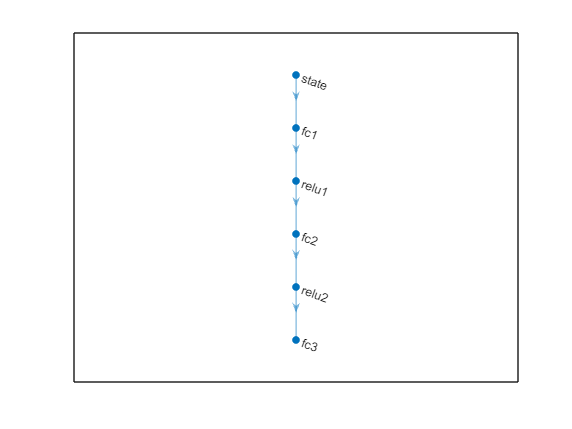

figure
plot(layerGraph(dnn))

Specify options for the critic optimizer using `rlOptimizerOptions`.

criticOptions = rlOptimizerOptions('LearnRate',1e-4,'GradientThreshold',1,'L2RegularizationFactor',1e-4);

Create the critic representation using the specified deep neural network and options. You must also specify the action and observation info for the critic, which you obtain from the environment interface. For more information, see [`rlVectorQValueFunction`](docid:rl_ref#mw_7a9361cb-5a3b-4aba-a231-0966c5966233).

critic = rlVectorQValueFunction(dnn,observationInfo,actionInfo);

To create the DQN agent, first specify the DQN agent options using [`rlDQNAgentOptions`](docid:rl_ref#mw_d66ae7b0-1964-4f66-a2ee-cfc08fc3657e).

agentOptions = rlDQNAgentOptions(...
    'SampleTime',Ts,...
    'UseDoubleDQN',true,...
    'CriticOptimizerOptions',criticOptions,...
    'ExperienceBufferLength',1e6,...
    'MiniBatchSize',64);

Then, create the DQN agent using the specified critic representation and agent options. For more information, see [`rlDQNAgent`](docid:rl_ref#mw_167d0061-c095-446e-828f-816916a0f227).

agent = rlDQNAgent(critic,agentOptions);

## Train Agent

To train the agent, first specify the training options. For this example, use the following options:

- Run each training episode for at most 5000 episodes, with each episode lasting at most `ceil(T/Ts)` time steps.

- Display the training progress in the Episode Manager dialog box (set the `Plots` option to `training-progress`) and disable the command line display (set the `Verbose` option to `false`).

- Stop training when the episode reward reaches `–1`. 

- Save a copy of the agent for each episode where the cumulative reward is greater than `–2.5`.

For more information, see [`rlTrainingOptions`](docid:rl_ref#mw_1f5122fe-cb3a-4c27-8c80-1ce46c013bf0).

maxepisodes = 5000;
maxsteps = ceil(T/Ts);
trainingOpts = rlTrainingOptions(...
    'MaxEpisodes',maxepisodes,...
    'MaxStepsPerEpisode',maxsteps,...
    'Verbose',false,...
    'Plots','training-progress',...
    'StopTrainingCriteria','EpisodeReward',...
    'StopTrainingValue',-1,...
    'SaveAgentCriteria','EpisodeReward',...
    'SaveAgentValue',-2.5);

Train the agent using the [`train`](docid:rl_ref#mw_c0ccd38c-bbe6-4609-a87d-52ebe4767852) function. Training is a computationally intensive process that takes several hours to complete. To save time while running this example, load a pretrained agent by setting `doTraining` to `false`. To train the agent yourself, set `doTraining` to `true`.

doTraining = false;




if doTraining    
    % Train the agent.
    trainingStats = train(agent,env,trainingOpts);
else
    % Load the pretrained agent for the example.
    load('/MATLAB Drive/deep_reinforcement_learning/savedAgents/TEST-1-MODEL/DQN-agent1-5000.mat','agent')       

end

## Simulate DQN Agent

To validate the performance of the trained agent, uncomment the following two lines and simulate the agent within the environment. For more information on agent simulation, see [`rlSimulationOptions`](docid:rl_ref#mw_983bb2e9-0115-4548-8daa-687037e090b2) and [`sim`](docid:rl_ref#mw_e6296379-23b5-4819-a13b-210681e153bf).

% simOptions = rlSimulationOptions('MaxSteps',maxsteps);
% experience = sim(env,agent,simOptions);

To demonstrate the trained agent on deterministic initial conditions, simulate the model in Simulink. 

e1_initial = 0.5;
e2_initial = -0.1;
u_min = -0.5;
u_max = 0.5;
sim(mdl)

Program interruption (Ctrl-C) has been detected.

## Reset Function

function in = localResetFcn(in)
    % reset
    in = setVariable(in,'e1_initial', 0.5*(-1+2*rand)); % random value for lateral deviation
    in = setVariable(in,'e2_initial', 0.1*(-1+2*rand)); % random value for relative yaw angle
end